## Runge-Kutta 4 method (similar to Kuznetsov)

Another Runge-Kutta 4 implementation using a small step.

Results don't match! (more similar to the paper than to the spiral).

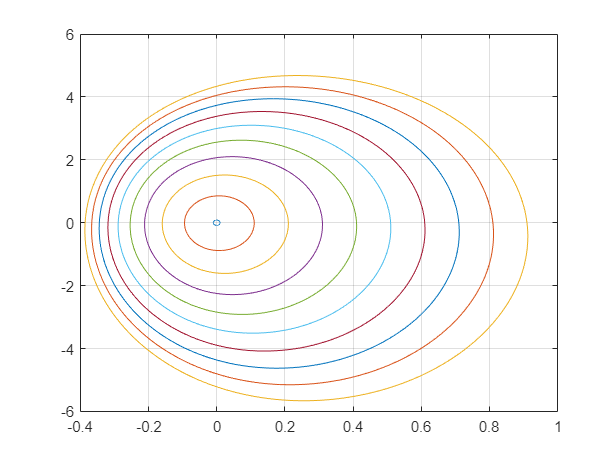

global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2

% a1=1;b1=1;c1=0;al1=0;bt1=1;
% a2=-10;b2=2.7;c2=0.4;al2=-437.5;bt2=0.003;
a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.2;c2=0.7;al2=-72-7/9;bt2=0.0015;



h=0.01;
x2=[];
T=[];
xdif=[];
j=1;
h=0.01;
for i=setdiff(1:10:100,0)
    x=[]; x(1) = i*h;
    y=[]; y(1) = 0;
    [x,y,T(j)] = RK4cycle(x,y,0.001);
    x2(j)=i*h;
    xdif(j)=x(end)-x(1);
    j=j+1;
    plot(x,y);
    hold on
end
grid on
hold off

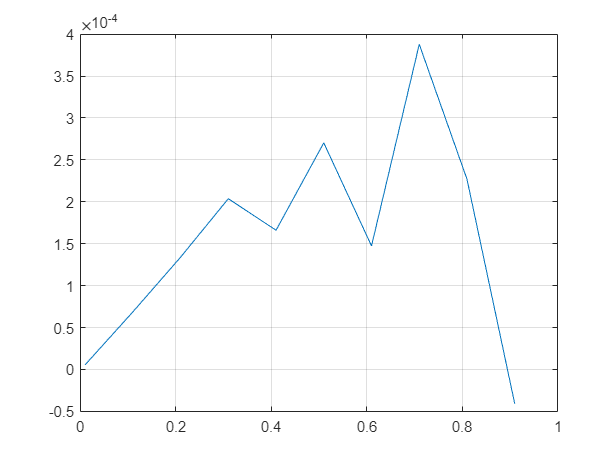

plot(x2,xdif);
grid on

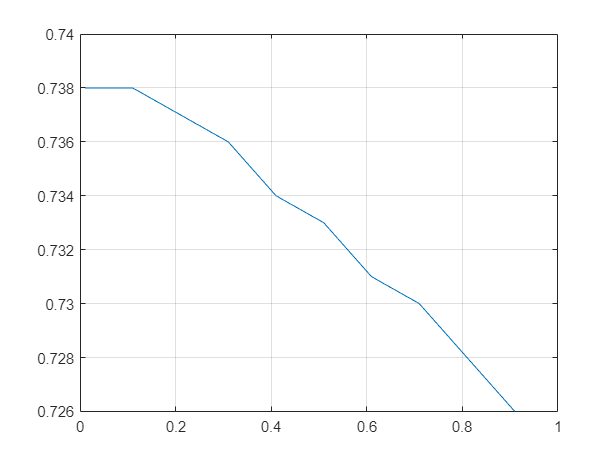

plot(x2,T);
grid on

## Functions

function dz=fQsys(t, z)
    global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
    dz=zeros(2,1); % z=(z(1),z(2))=(x,y)
    
    dz(1)=(a1 * z(1)^2+ b1 * z(1)* z(2)+ c1 * z(2)^2+ al1 * z(1)+ bt1 * z(2));
    dz(2)=(a2 * z(1)^2+ b2 * z(1)* z(2)+ c2 * z(2)^2+ al2 * z(1)+ bt2 * z(2));
end

function [x,y,T] = RK4cycle(x,y,h)
    
    % Runge-Kutta 4

        for i=1:1:2

            k1=fQsys(i*h, [x(i), y(i)]);
        
            k2=fQsys(i*h+h/2, [x(i)+h/2*k1(1), y(i)+h/2*k1(2)]);
            
            k3=fQsys(i*h+h/2, [x(i)+h/2*k2(1), y(i)+h/2*k2(2)]);
            
            k4=fQsys(i*h+h, [x(i)+h*k3(1), y(i)+h*k3(2)]);
            
            x(i+1)=x(i) + h/6*(k1(1)+2*k2(1)+2*k3(1)+k4(1));
            y(i+1)=y(i) + h/6*(k1(2)+2*k2(2)+2*k3(2)+k4(2));
                    
        end

        i=3;

        while y(i)*y(i-1)>0

            k1=fQsys(i*h, [x(i), y(i)]);
                    
            k2=fQsys(i*h+h/2, [x(i)+h/2*k1(1), y(i)+h/2*k1(2)]);
            
            k3=fQsys(i*h+h/2, [x(i)+h/2*k2(1), y(i)+h/2*k2(2)]);
            
            k4=fQsys(i*h+h, [x(i)+h*k3(1), y(i)+h*k3(2)]);
            
            x(i+1)=x(i) + h/6*(k1(1)+2*k2(1)+2*k3(1)+k4(1));
            y(i+1)=y(i) + h/6*(k1(2)+2*k2(2)+2*k3(2)+k4(2));
            i=i+1;
        end
        
        j=i;

        for i=i:1:i+2

            k1=fQsys(i*h, [x(i), y(i)]);
                    
            k2=fQsys(i*h+h/2, [x(i)+h/2*k1(1), y(i)+h/2*k1(2)]);
            
            k3=fQsys(i*h+h/2, [x(i)+h/2*k2(1), y(i)+h/2*k2(2)]);
            
            k4=fQsys(i*h+h, [x(i)+h*k3(1), y(i)+h*k3(2)]);
            
            x(i+1)=x(i) + h/6*(k1(1)+2*k2(1)+2*k3(1)+k4(1));
            y(i+1)=y(i) + h/6*(k1(2)+2*k2(2)+2*k3(2)+k4(2));
        
        end
        
        i=j+2;
        while y(i)*y(i-1)>0

            k1=fQsys(i*h, [x(i), y(i)]);
                    
            k2=fQsys(i*h+h/2, [x(i)+h/2*k1(1), y(i)+h/2*k1(2)]);
            
            k3=fQsys(i*h+h/2, [x(i)+h/2*k2(1), y(i)+h/2*k2(2)]);
            
            k4=fQsys(i*h+h, [x(i)+h*k3(1), y(i)+h*k3(2)]);
            
            x(i+1)=x(i) + h/6*(k1(1)+2*k2(1)+2*k3(1)+k4(1));
            y(i+1)=y(i) + h/6*(k1(2)+2*k2(2)+2*k3(2)+k4(2));
            i=i+1;
        end
        T=i*h;
end